# **Esercitazione 3 - EMG**

8 prove in 4 condizioni diverse.

Condizione 1 (prove 1 e 2): i soggetti dovevano compiere movimenti piccoli e lenti.

Condizione 2 (prove 3 e 4): movimenti piccoli e veloci.

Condizione 3 (prove 5 e 6): movimenti grandi e lenti.

Condizione 4 (prove 7 e 8): movimenti grandi e veloci.

load("emg_data.mat")

% segnale = cell2mat(emg_data(1,1));
% figure 
% plot((segnale(:,2)))
% hold on
% plot( (segnale(:,3)))

% %time
% [num_casi, num_soggetti]= size (emg_data);
% 
% %prealloco cell array
% time = cell (num_casi, num_soggetti);
% 
% for index_soggetto = 1: num_soggetti
% for index_caso = 1: num_casi
%     
%    signal = cell2mat(emg_data(index_caso, index_soggetto))
%    time {index_caso, index_soggetto} = signal(:,1);
% end
% end

*Obiettivo 1: Estrarre l’inviluppo del segnale EMG per ogni soggetto per ogni prova. *

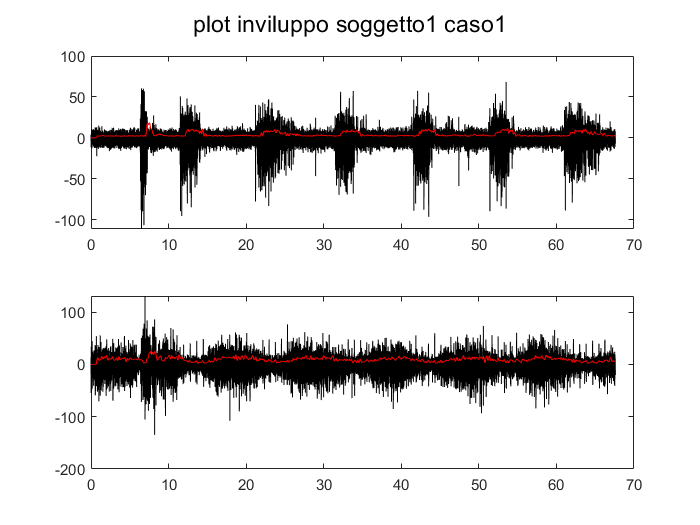

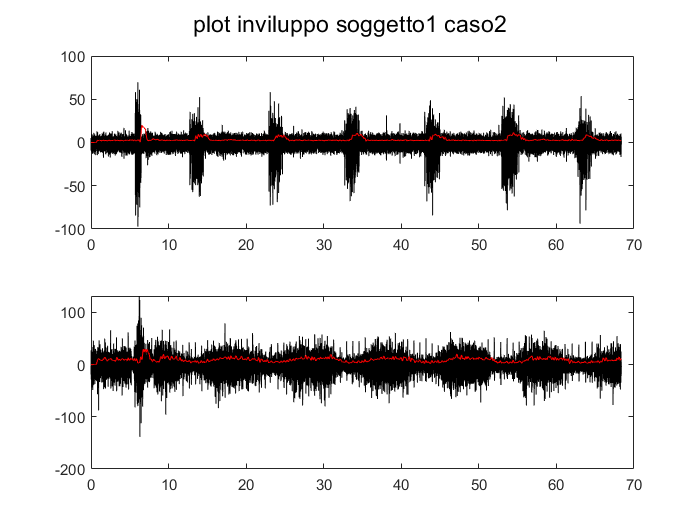

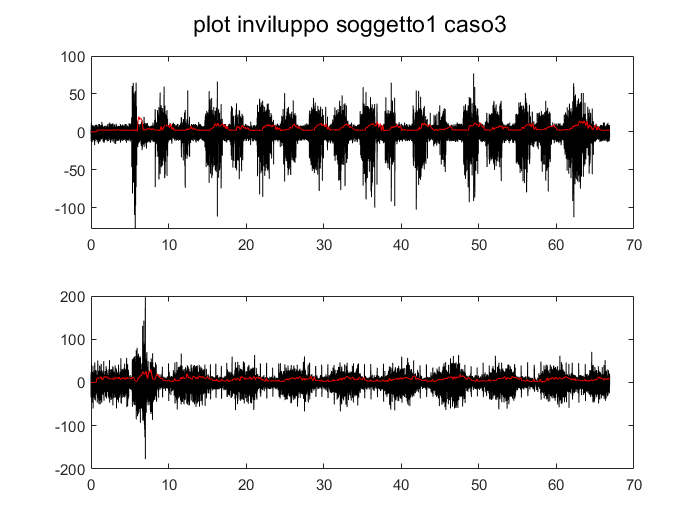

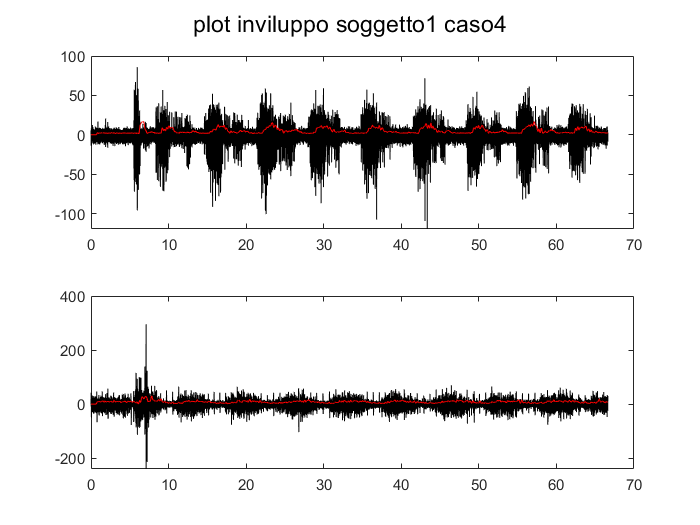

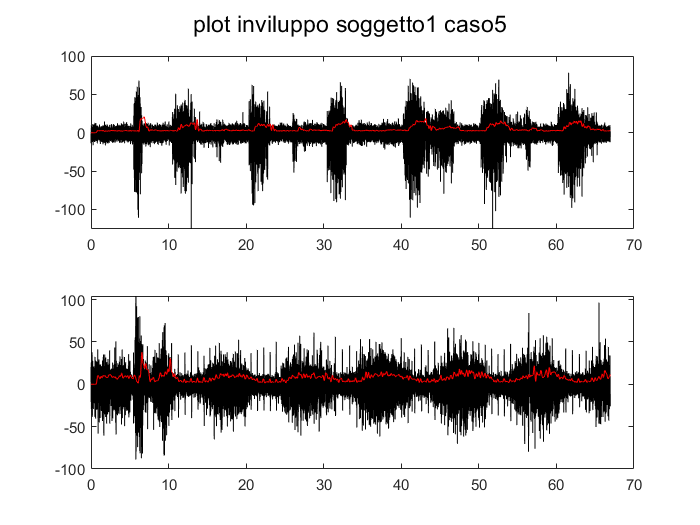

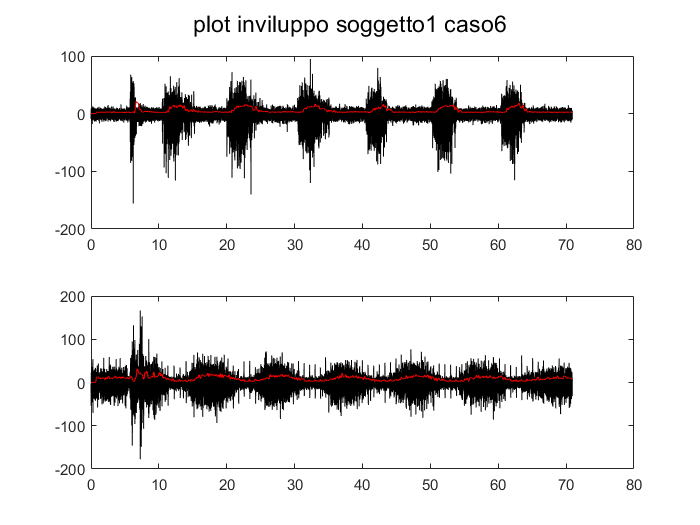

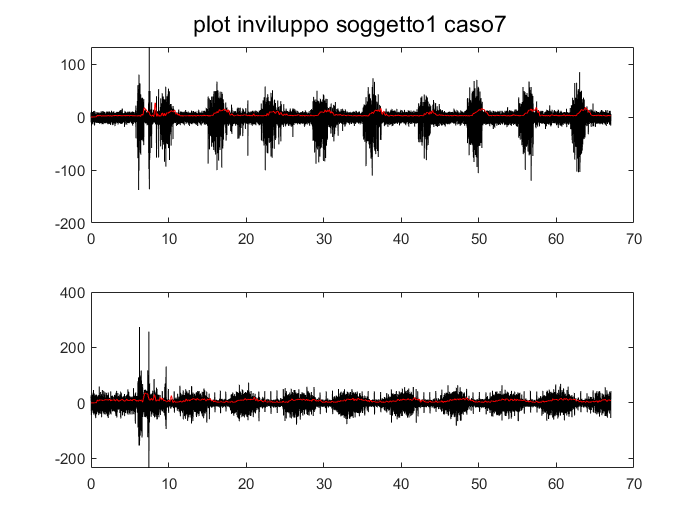

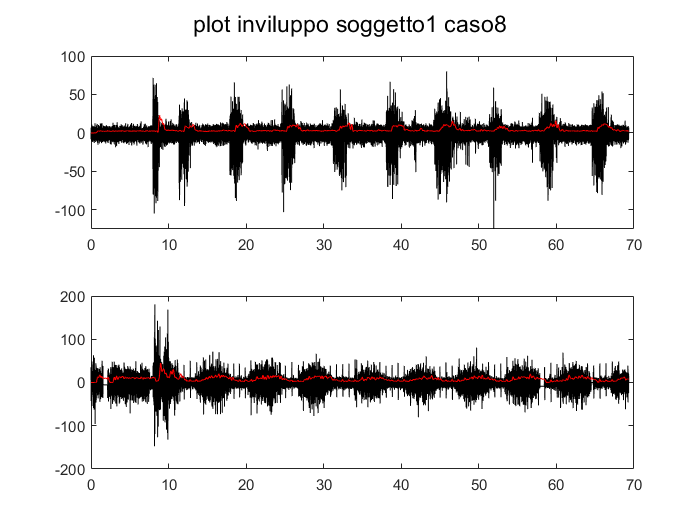

%uso della funzione get_envelope() 

fs = 2000;
nfft= 2048;

[inviluppo, T] = get_envelope (emg_data, fs, nfft);

*Obiettivo 2: Normalizzazione del segnale EMG rispetto al massimo valore di ogni soggetto. *

thr1 = single
1.8415

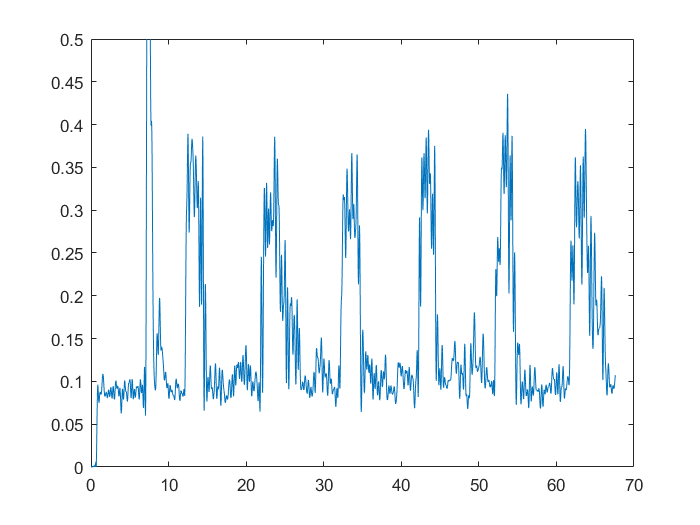

thr1 = single
7.3856

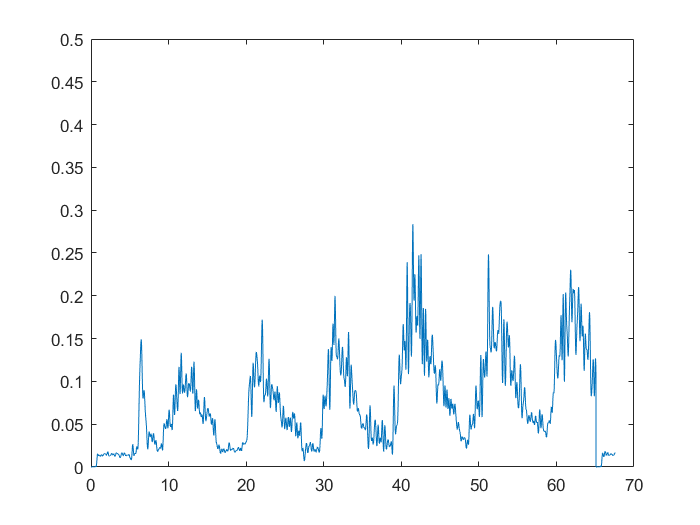

thr1 = single
3.0103

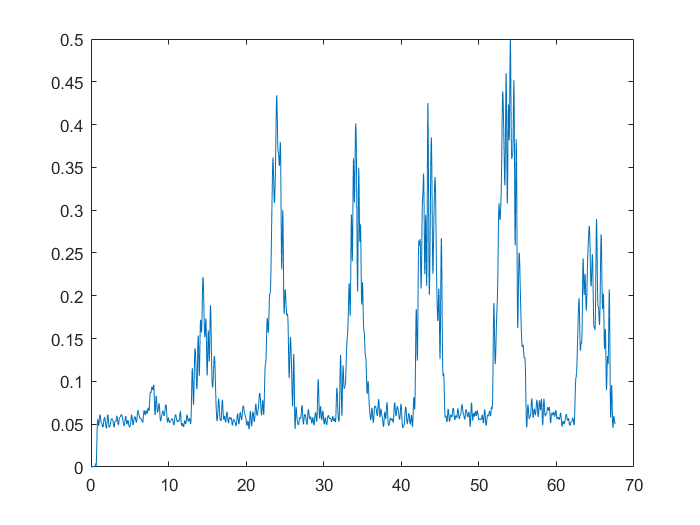

%uso funzione data_normalization()
signal = cell2mat(emg_data(1, 1));
time = signal(:,1);
norm=data_normalization(inviluppo, time); 

*Obiettivo 3: Calcolare lo spettro medio per ogni soggetto per ogni muscolo.*

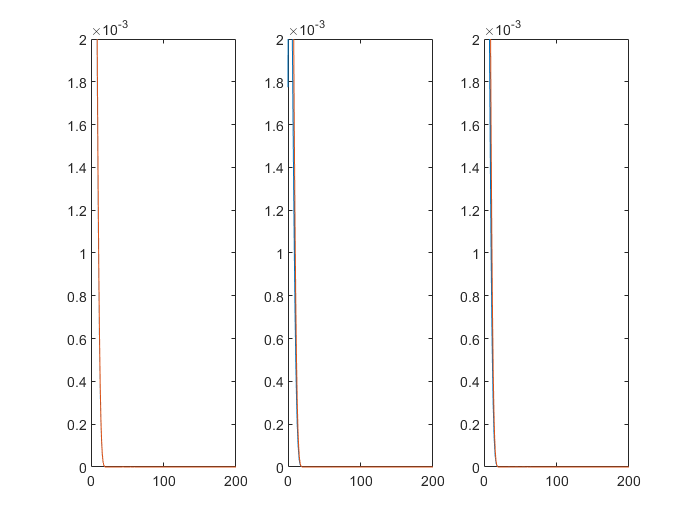

overlap=100;
window=200;

%utilizzo funzione meanpsd() per il calcolo e la visualizzazione dello
%spettro di potenza medio di ciascun muscolo di ogni soggetto
meanpsd(norm,overlap,window,nfft,fs);

*Obiettivo 4: Trovare le attivazioni per ogni soggetto e per ogni prova.*

%uso funzione detect_activation()

[peaks,time_peaks]=detect_activation(norm, T, 0.5);       

*Obiettivo 5: Visualizzazione delle singole attivazioni nelle 4 condizioni.*

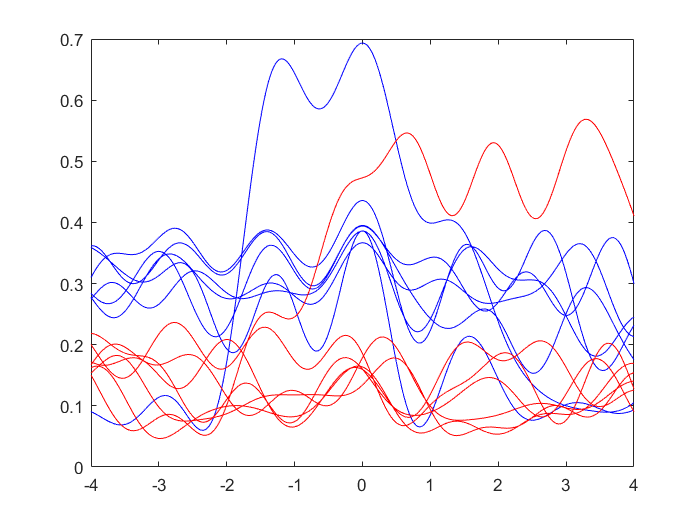

[num_casi, num_soggetti]= size (norm);

%numero finetstre è il numero di picchi
[casi, sei]=size(time_peaks);
N=zeros(casi,sei);
distanza=zeros(casi, sei);


for index_sei=1:sei
for index_casi=1:casi
        N(index_casi, index_sei)=length(cell2mat(peaks(index_casi, index_sei)));
        differenza= diff(cell2mat(time_peaks (index_casi, index_sei)));
        distanza (index_casi, index_sei)=min (differenza);
end
end

%lunghezza della finestra
M=floor(min(distanza,[], 'all'));

M=M/3;

%asse x, potrebbero essere gli indici
%ma per assex vorrei il tempo non gli indici
%inutile
axes=linspace(-M/2,M/2,M);
tempoindici=cell2mat(time_peaks(1,1));


qualcosa=cell2mat(norm(1,1));

figure

asse= linspace(-4,4, M+1);


for index=1:N(1,1)

unpicco1=qualcosa(tempoindici(index)-floor(M/2) : tempoindici(index)+floor(M/2), 1);
plot(asse, unpicco1, 'color', 'b')
hold on
end
for index=1:N(1,2)
unpicco2=qualcosa(tempoindici(index)-floor(M/2) : tempoindici(index)+floor(M/2), 2);
plot(asse, unpicco2, 'color', 'r')
hold on
end

ans = 7

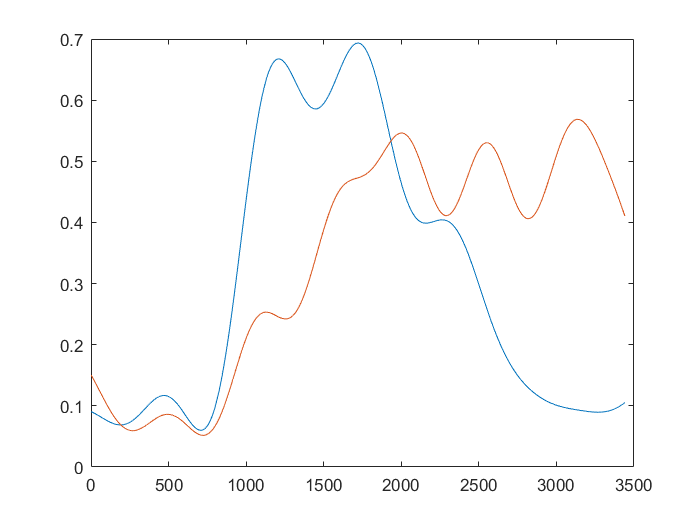

ans = 7

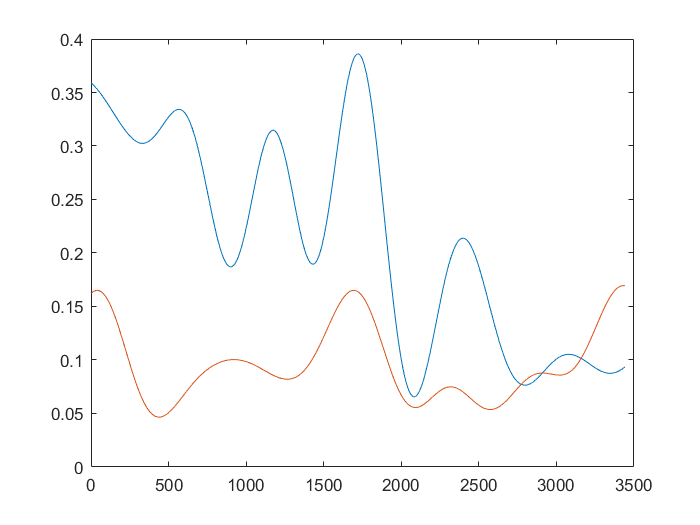

ans = 7

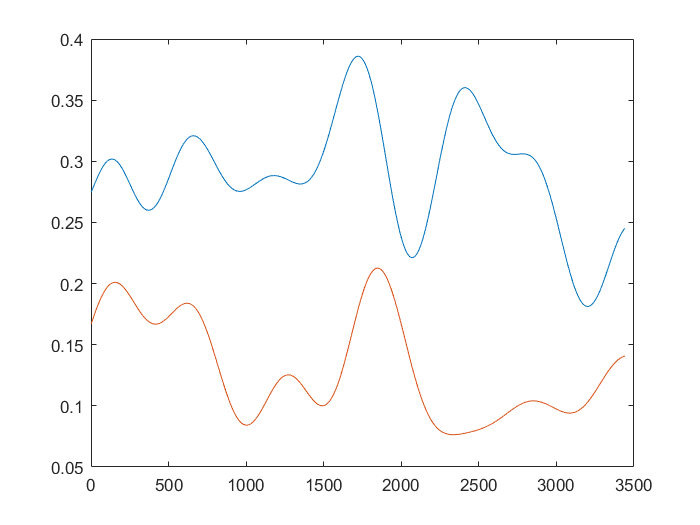

ans = 7

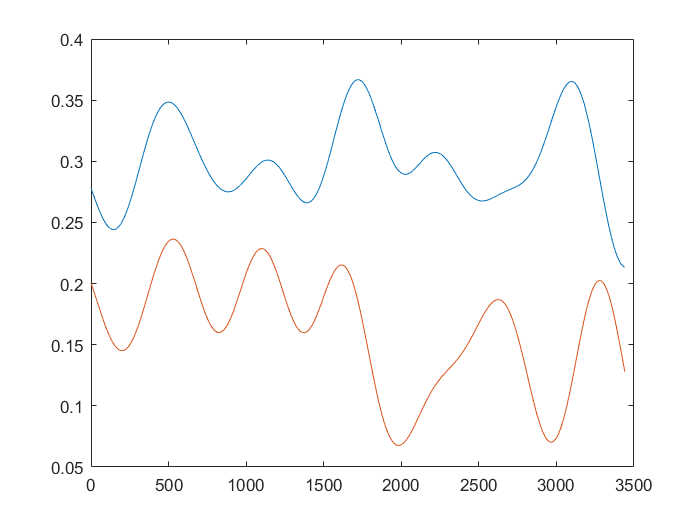

ans = 7

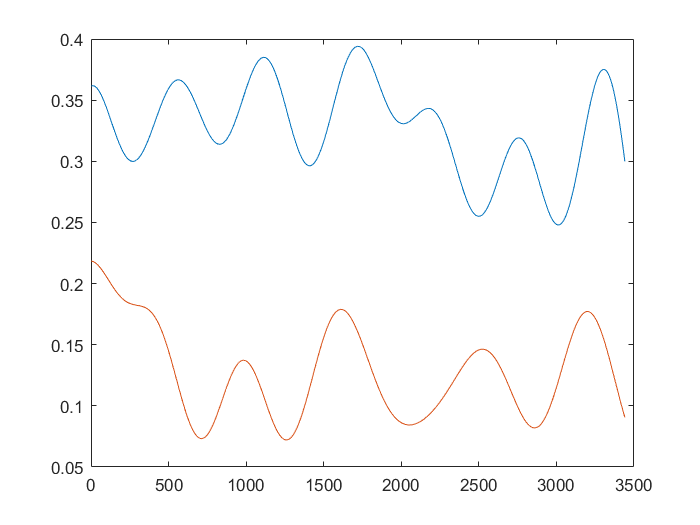

ans = 7

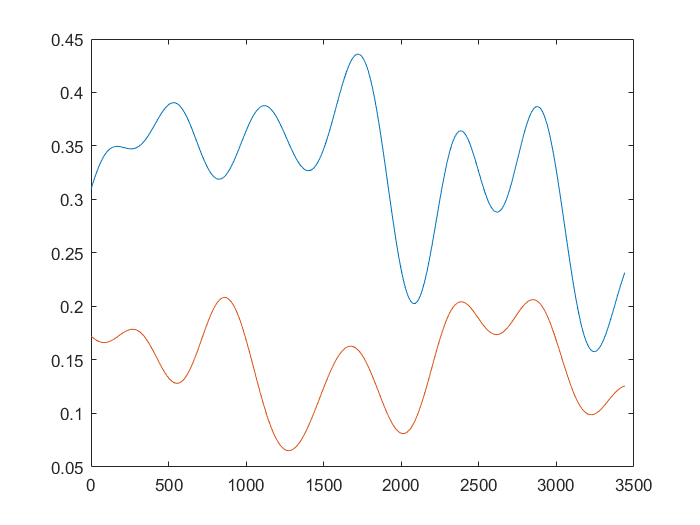

ans = 7

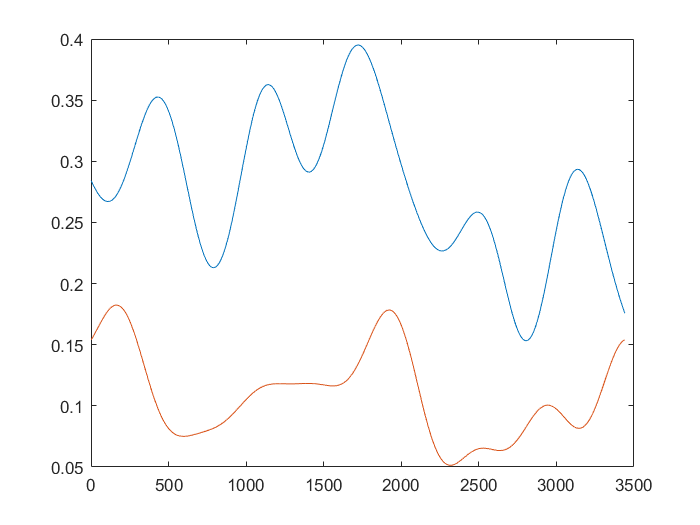

ans = 7

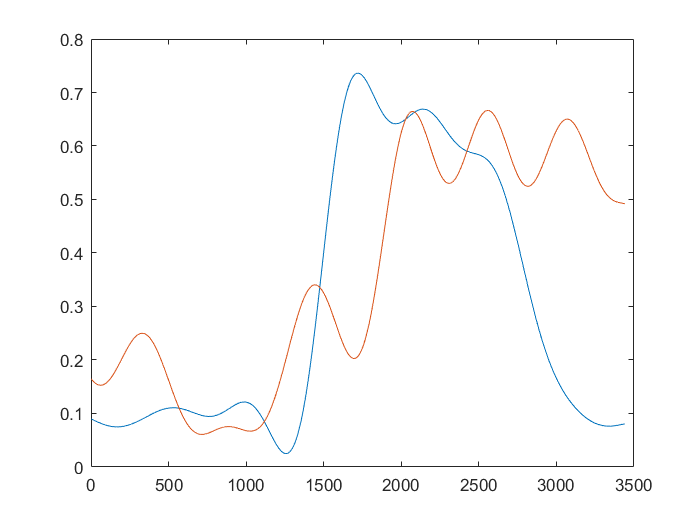

ans = 7

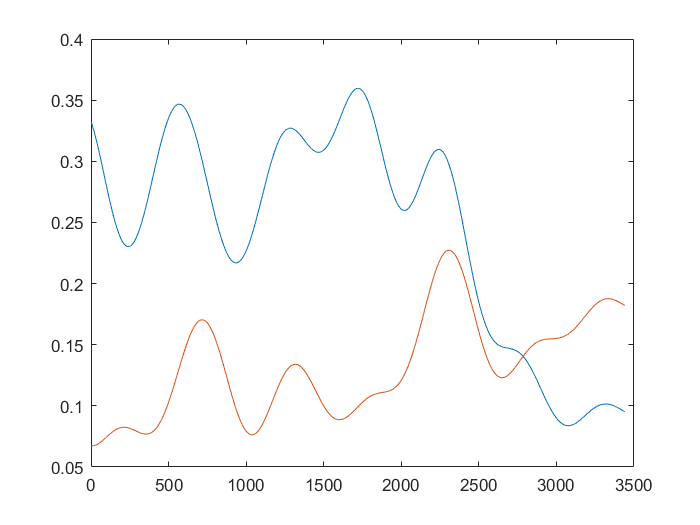

ans = 7

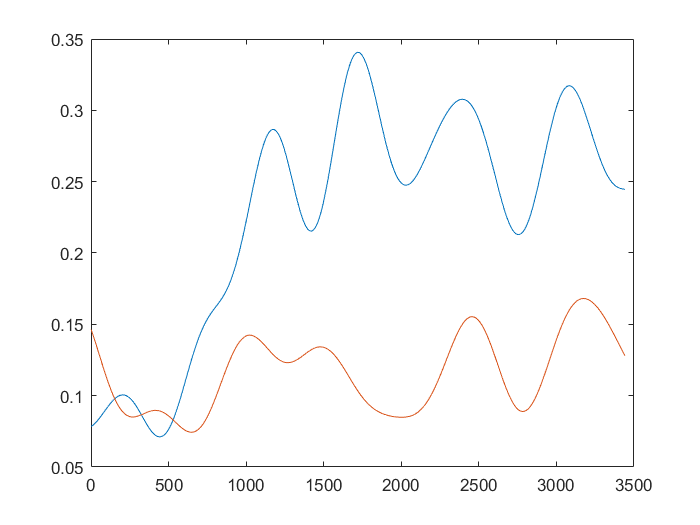

ans = 7

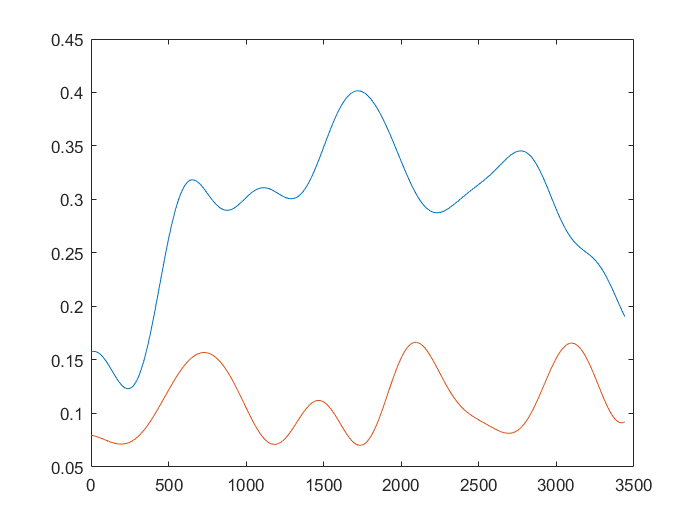

ans = 7

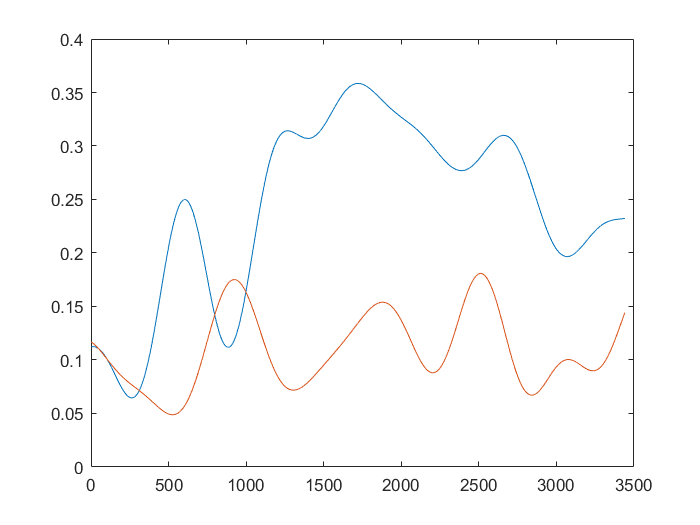

ans = 7

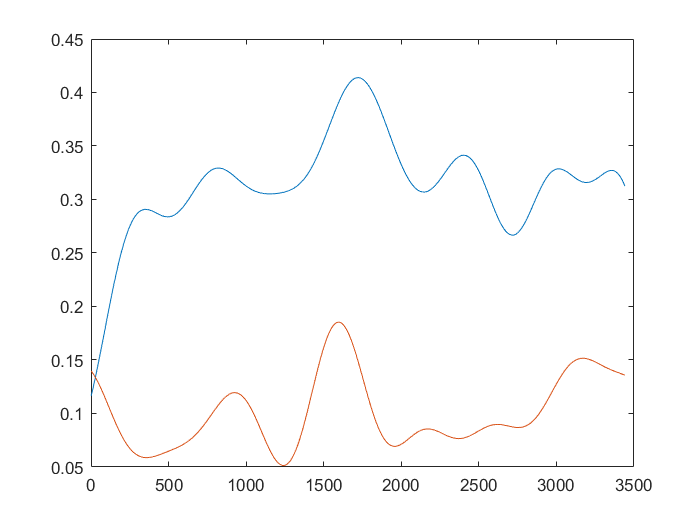

ans = 7

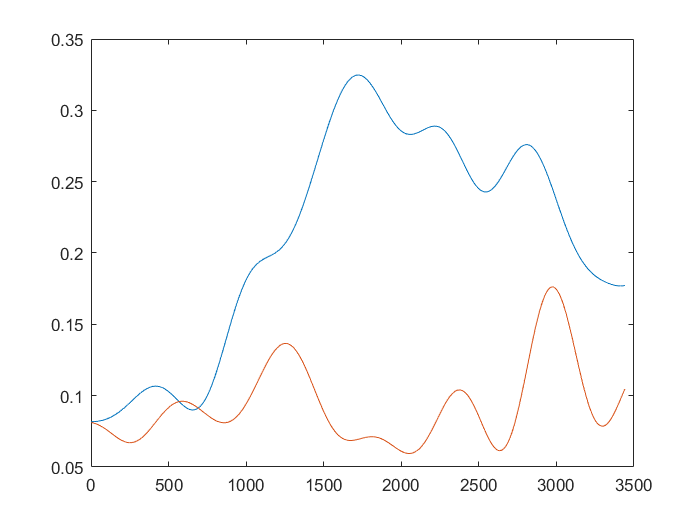

ans = 9

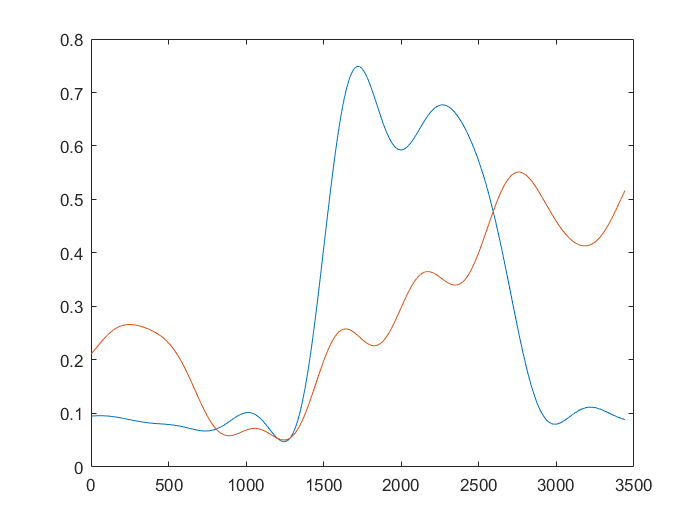

ans = 9

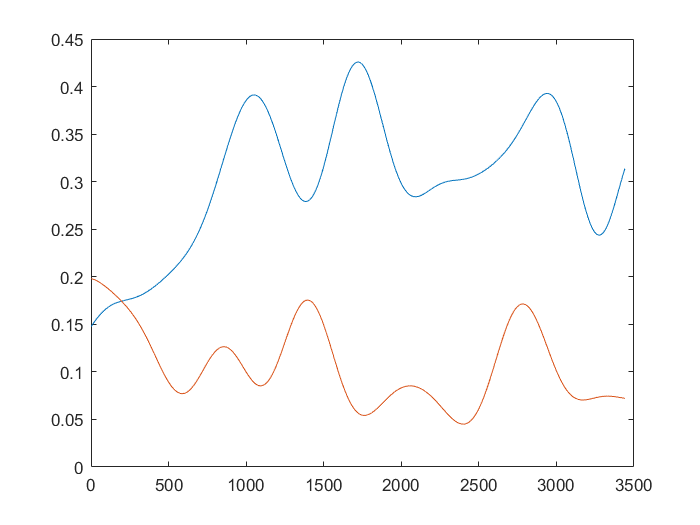

ans = 9

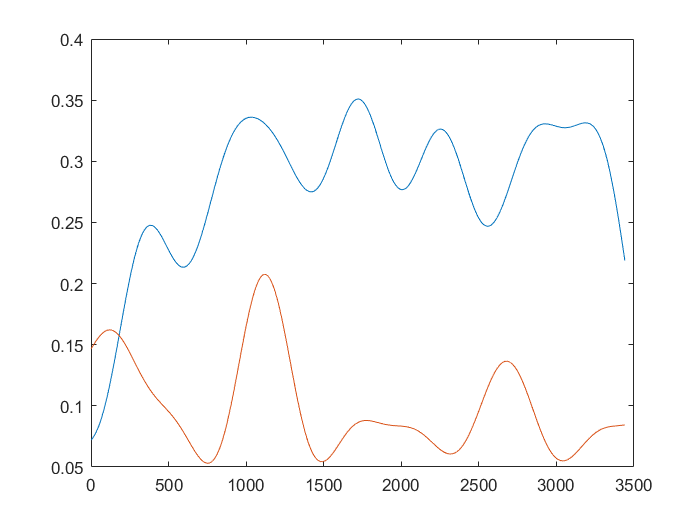

ans = 9

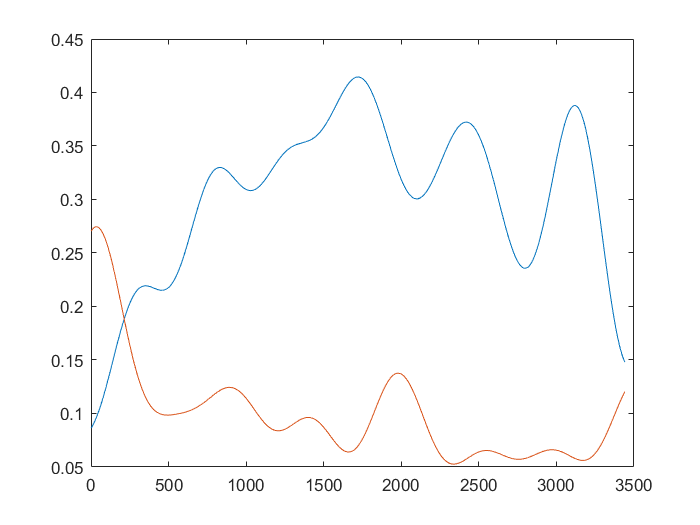

ans = 9

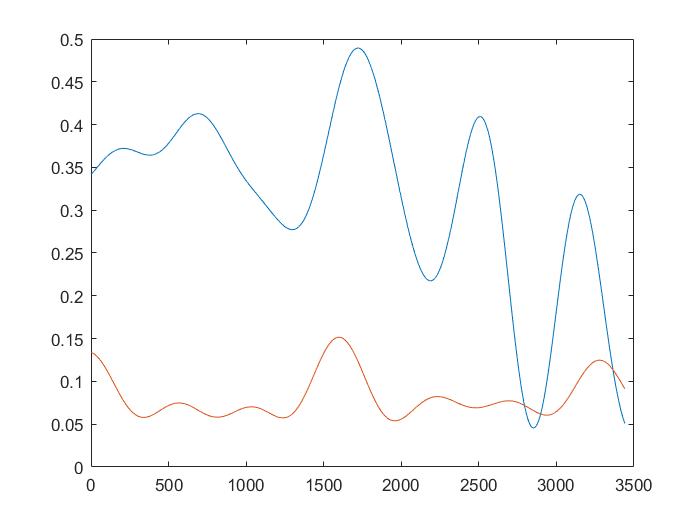

ans = 9

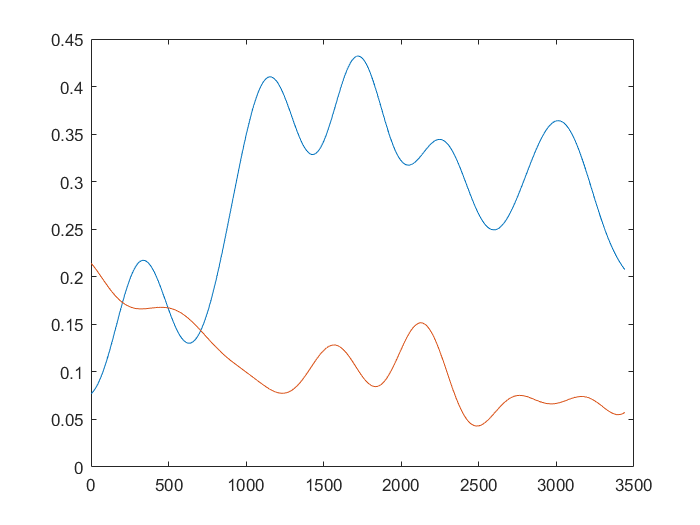

ans = 9

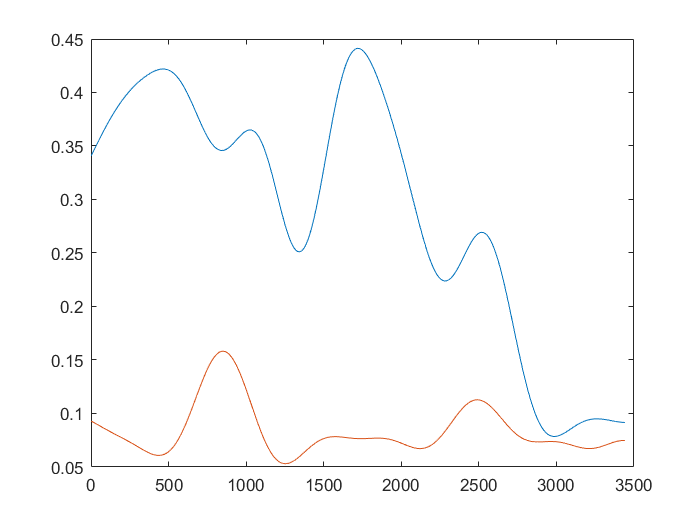

ans = 9

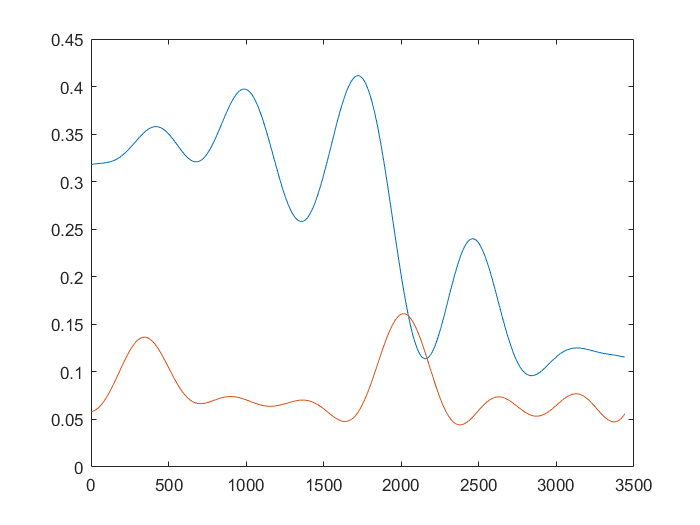

ans = 9

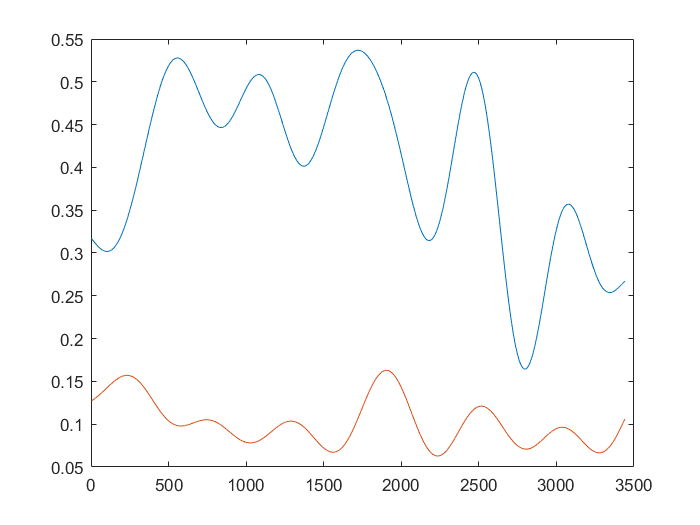

ans = 9

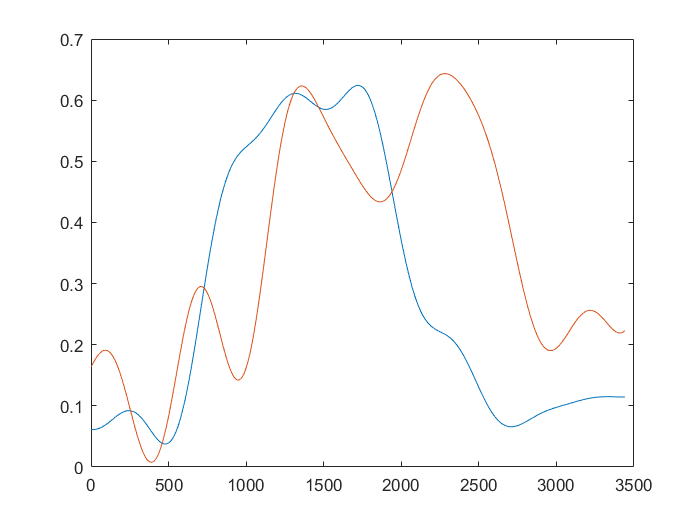

ans = 9

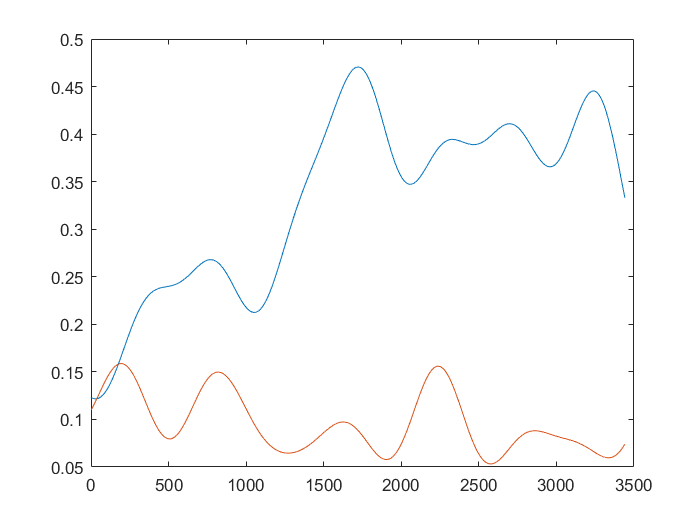

ans = 9

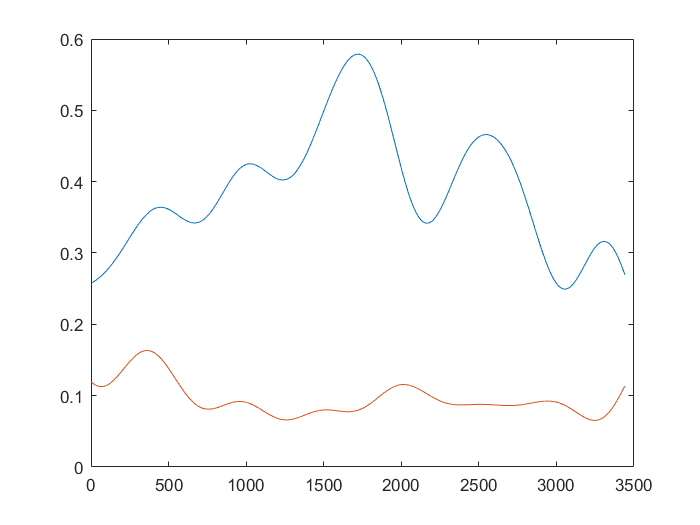

ans = 9

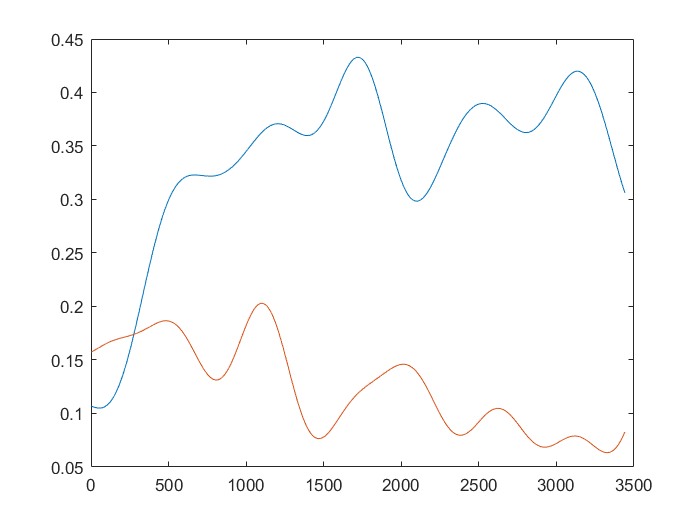

ans = 9

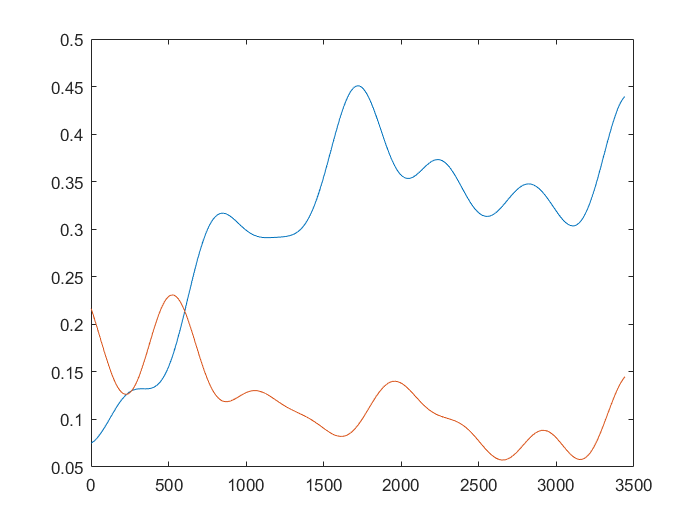

ans = 9

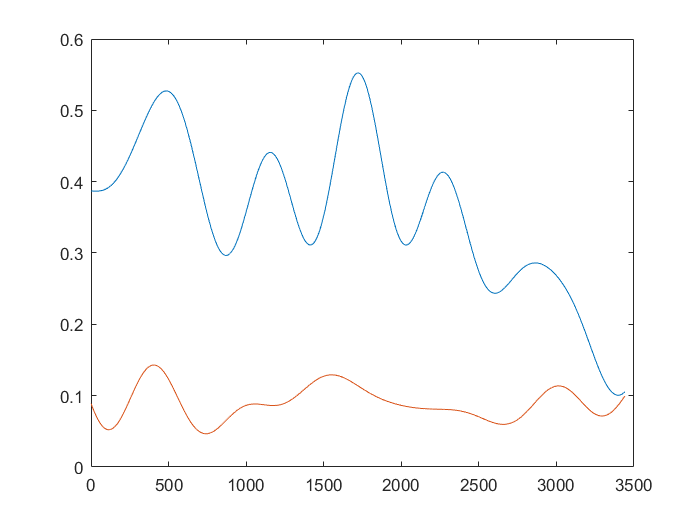

ans = 9

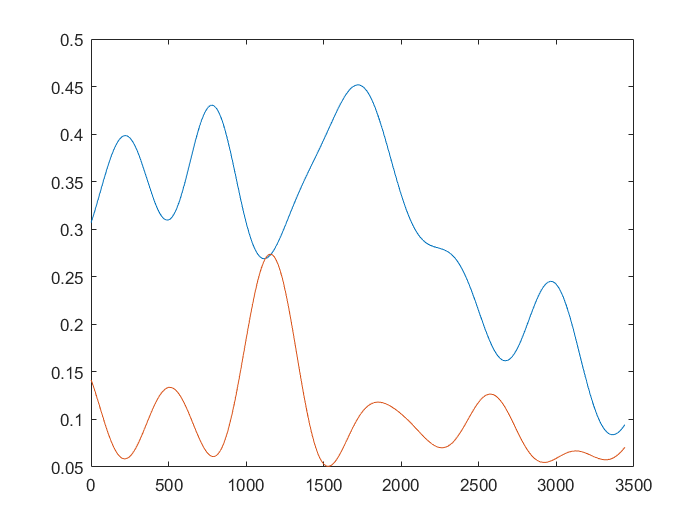

ans = 9

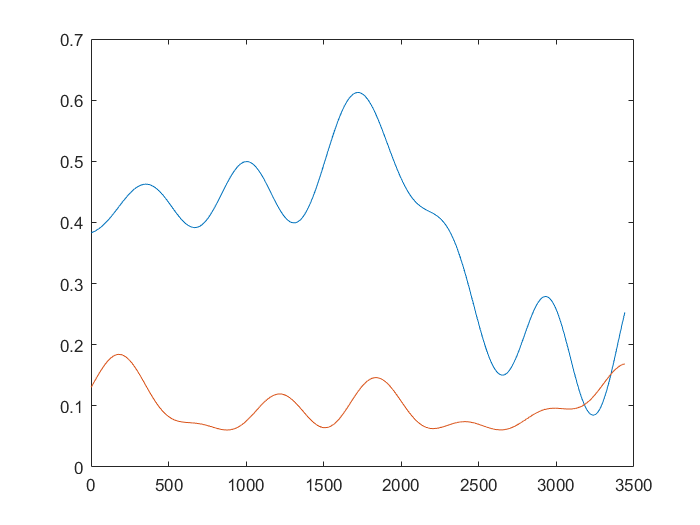

ans = 9

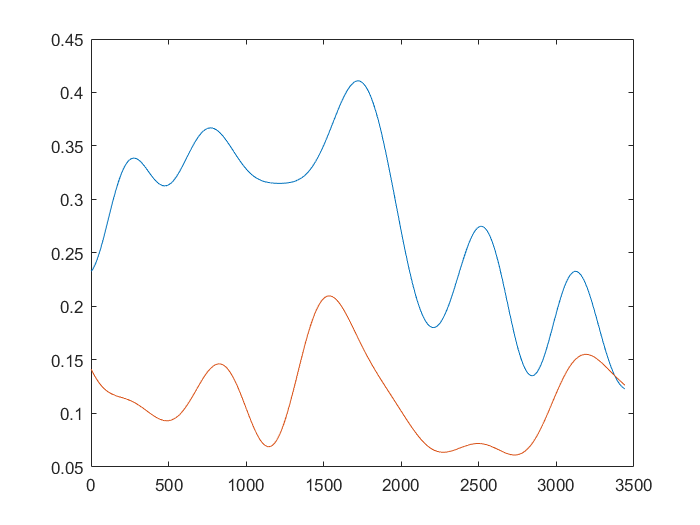

ans = 8

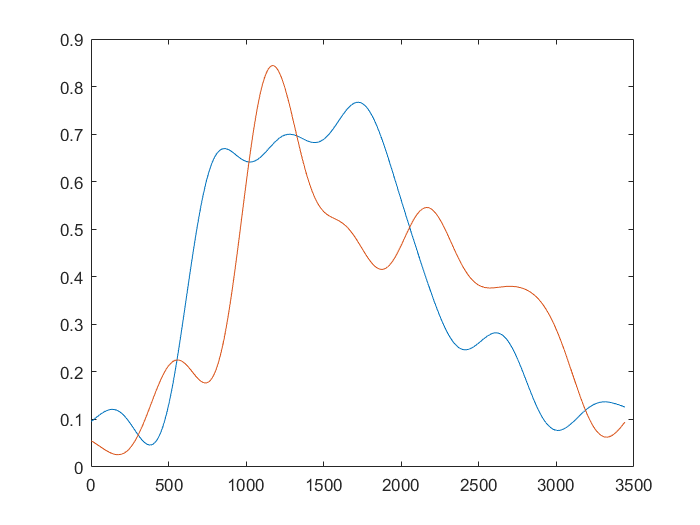

ans = 8

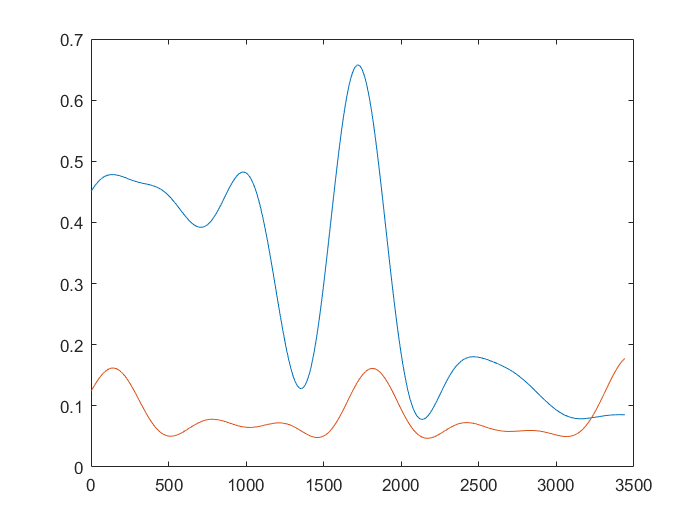

ans = 8

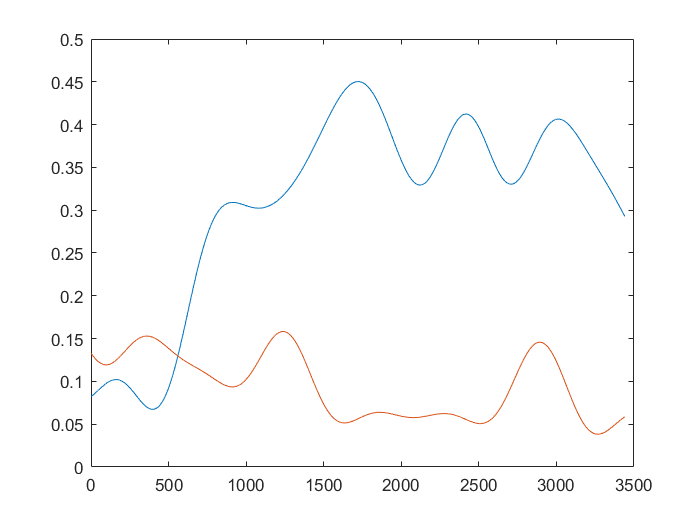

ans = 8

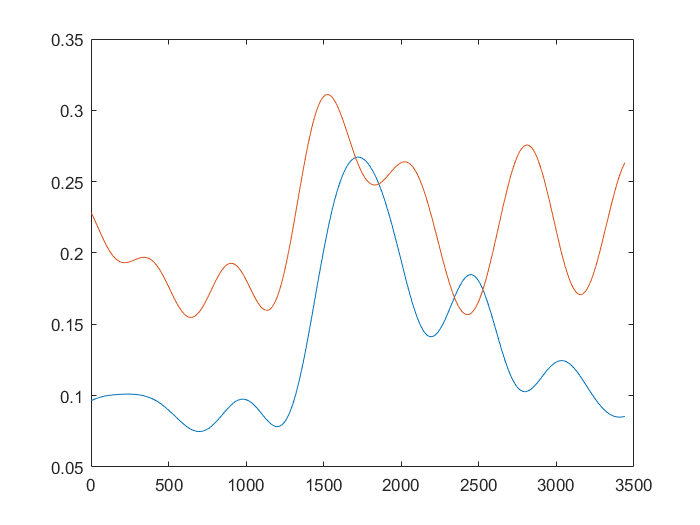

ans = 8

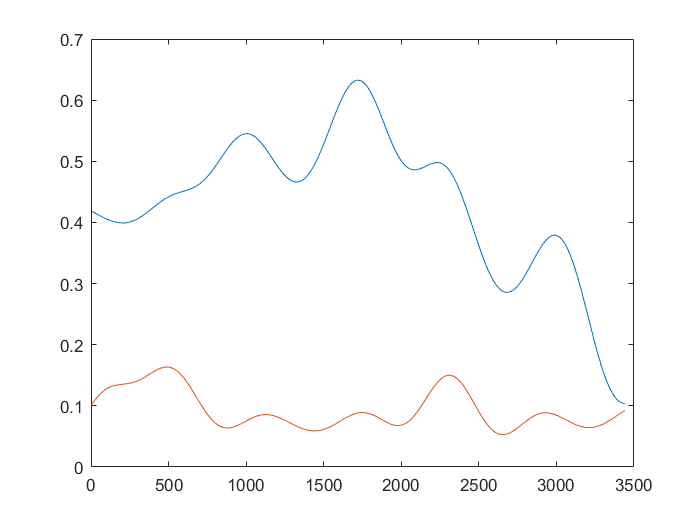

ans = 8

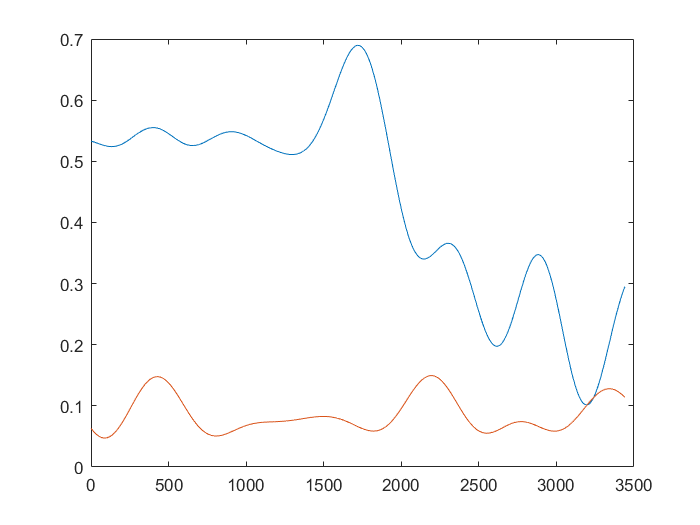

ans = 8

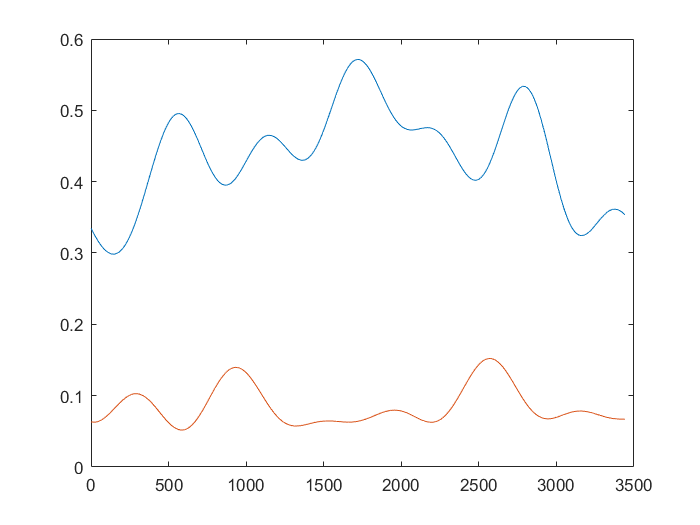

ans = 8

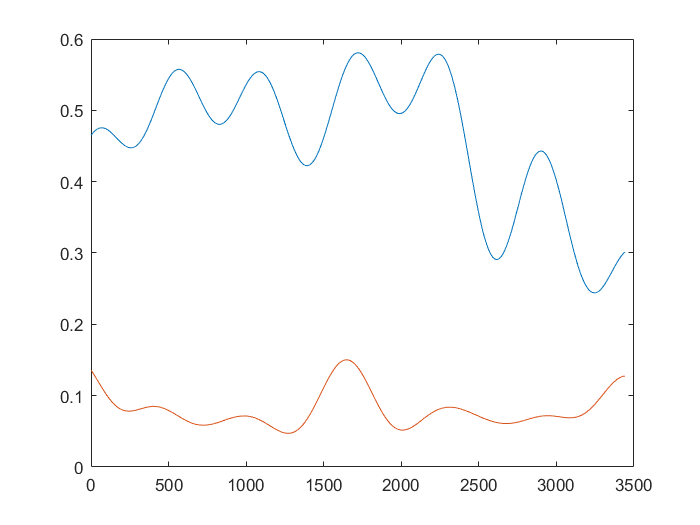

ans = 7

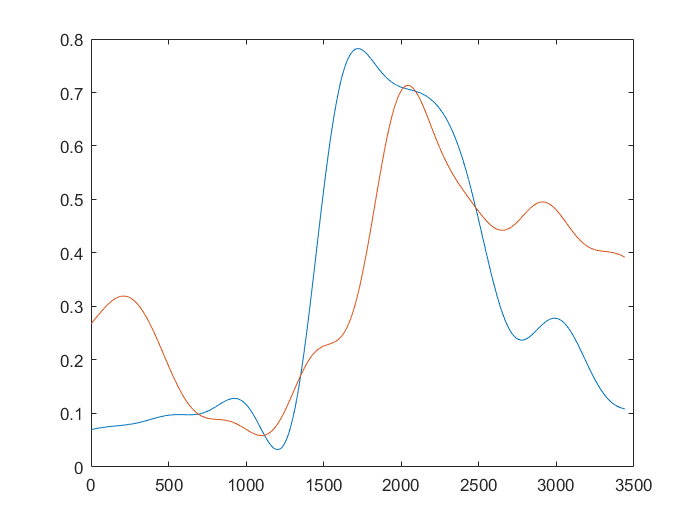

ans = 7

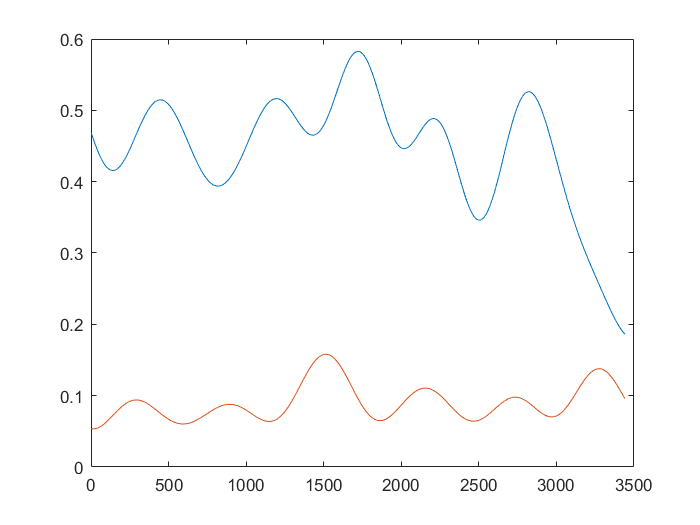

ans = 7

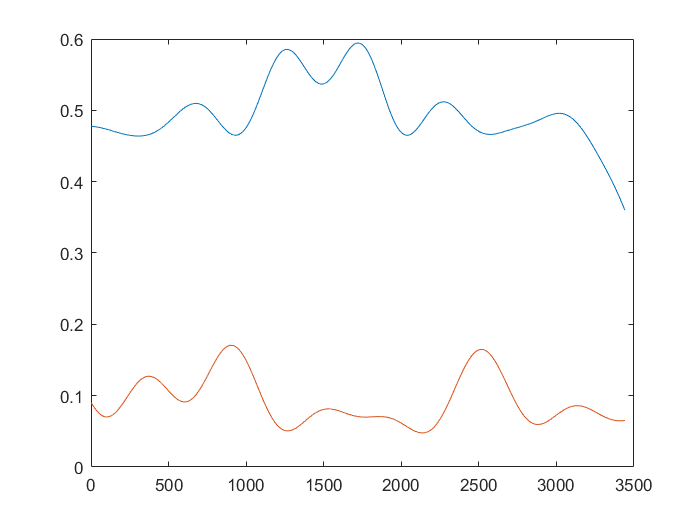

ans = 7

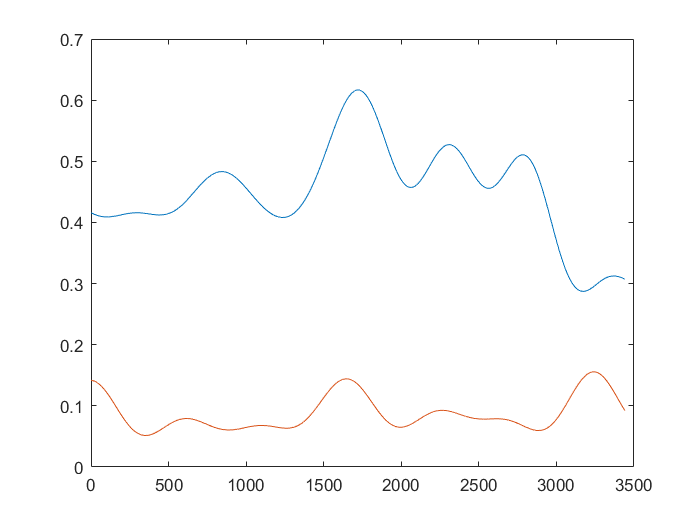

ans = 7

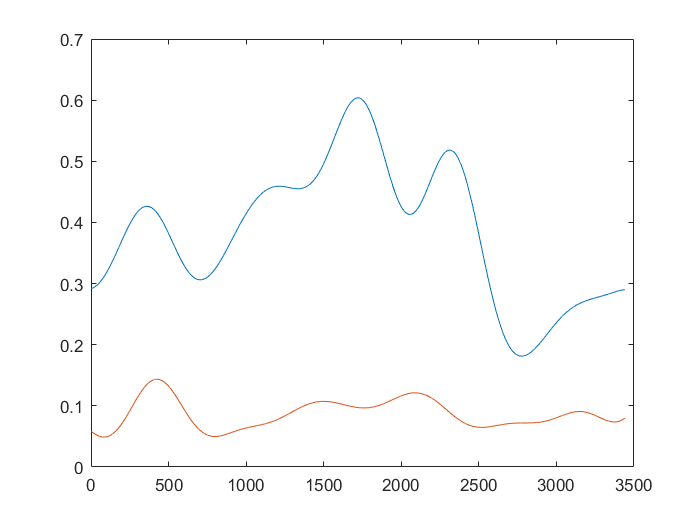

ans = 7

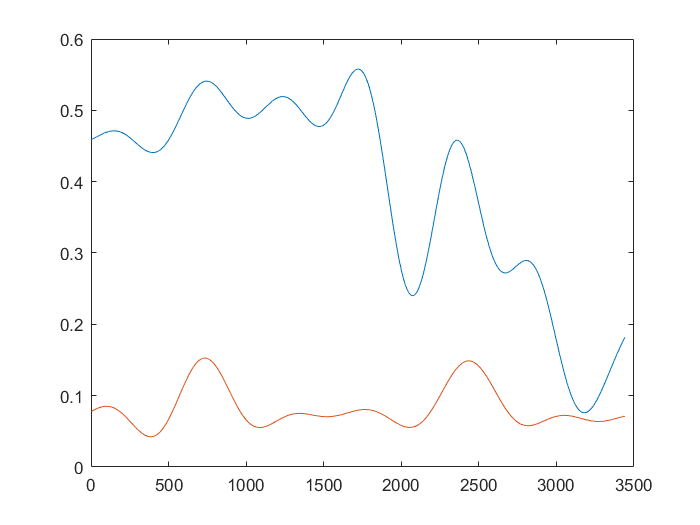

ans = 7

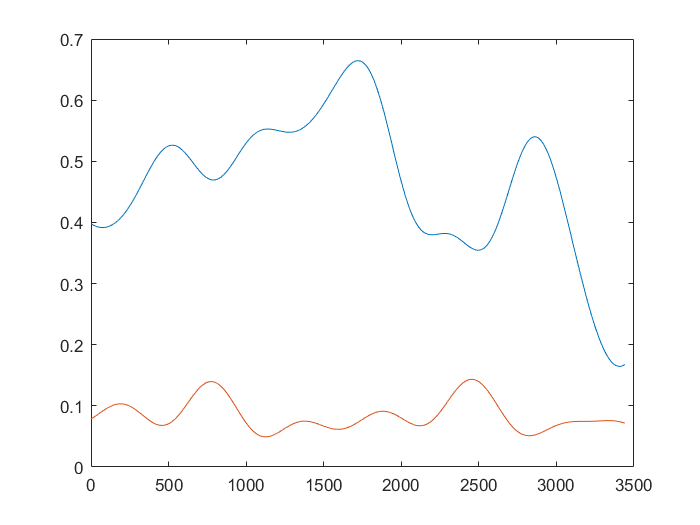

ans = 9

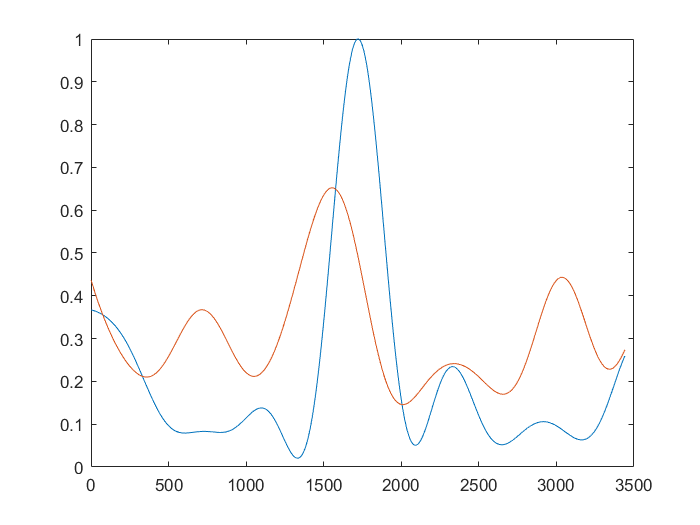

ans = 9

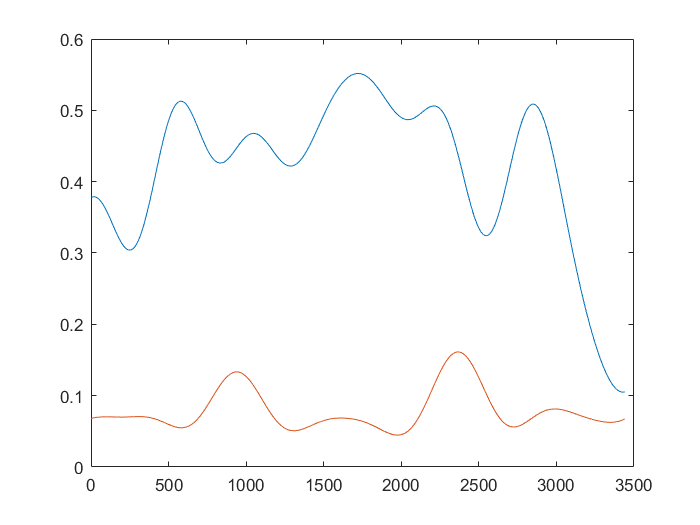

ans = 9

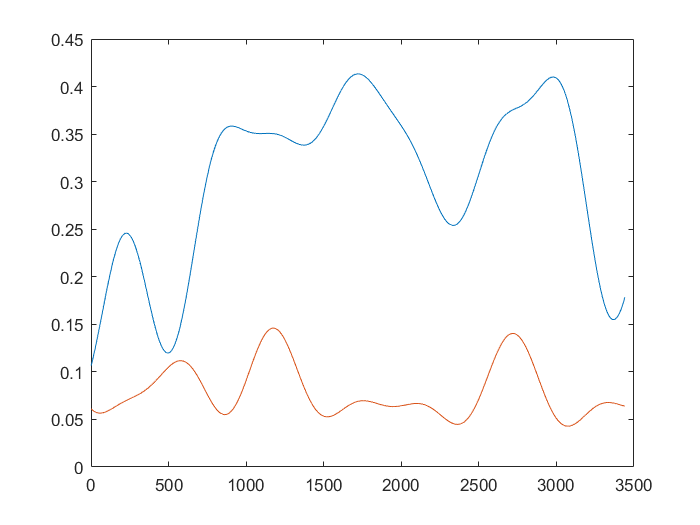

ans = 9

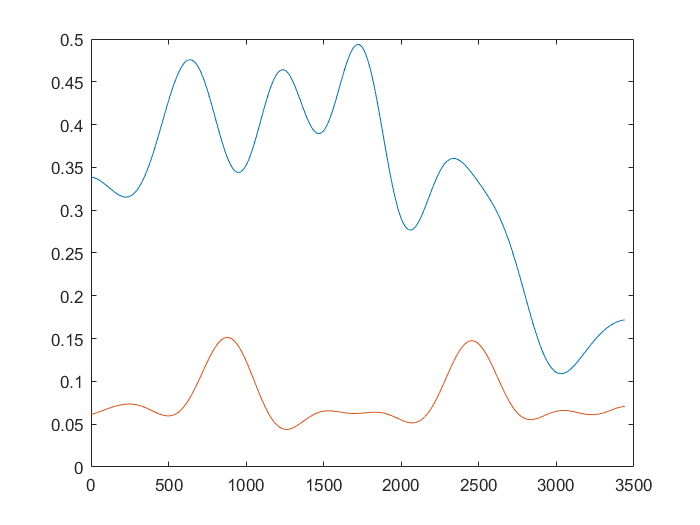

ans = 9

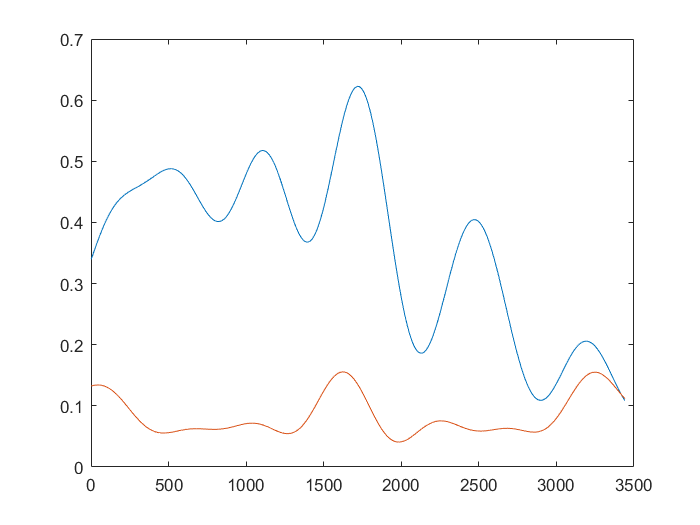

ans = 9

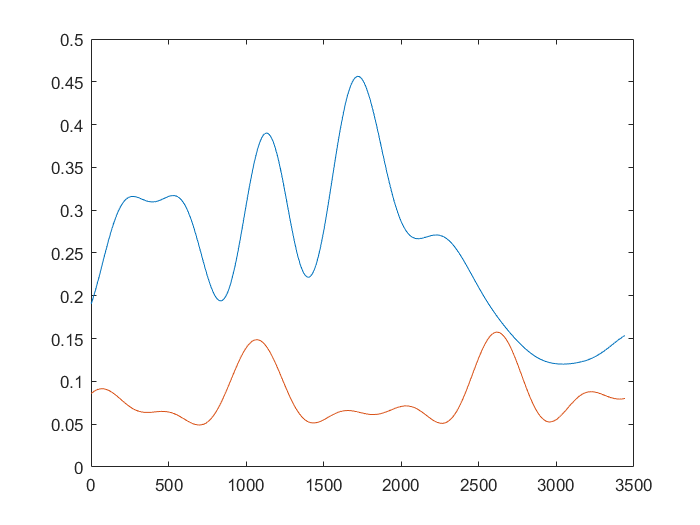

ans = 9

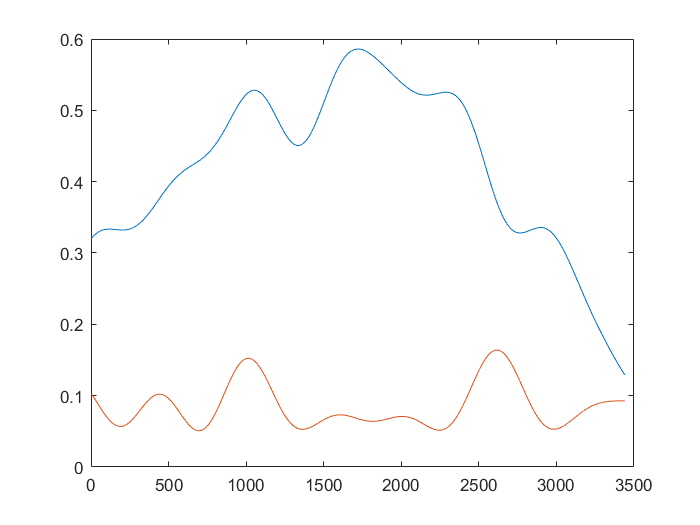

ans = 9

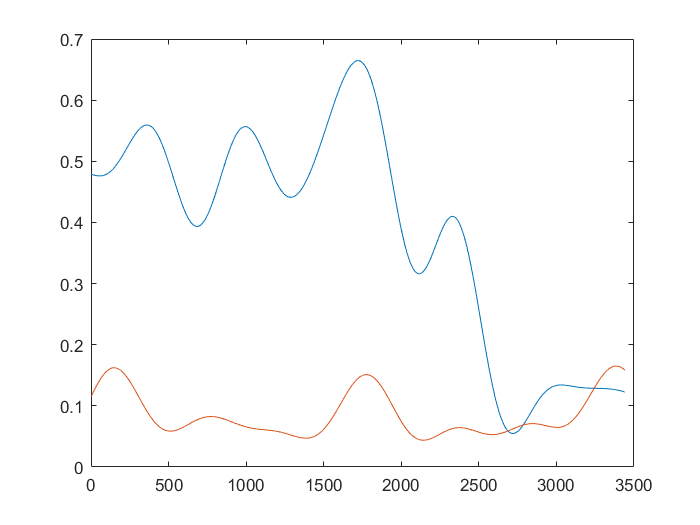

ans = 9

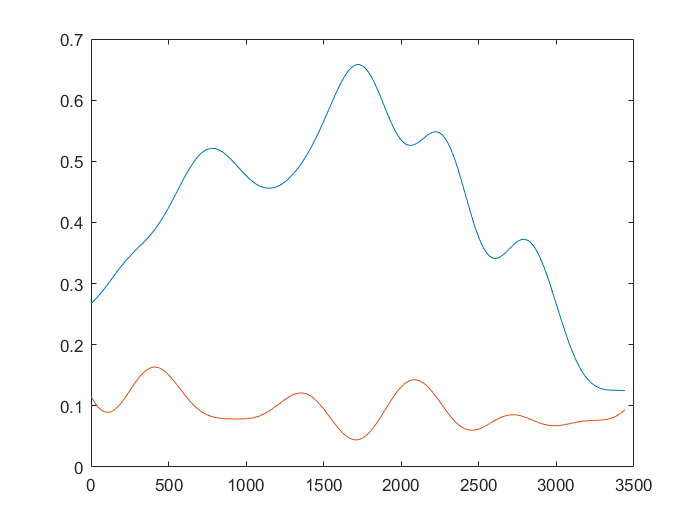

ans = 9

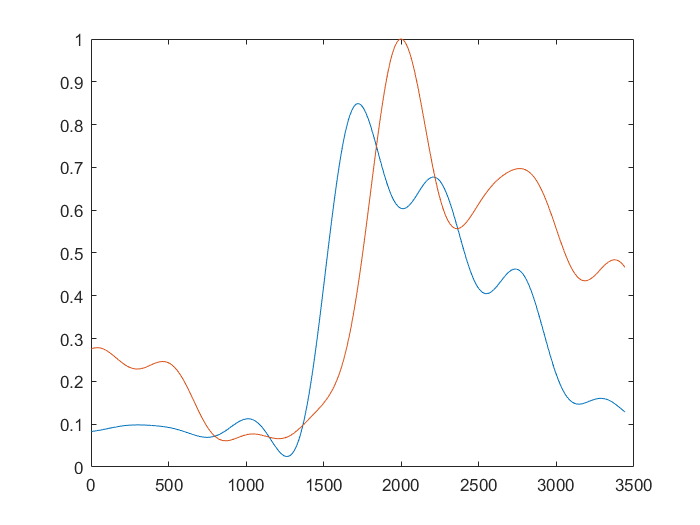

ans = 9

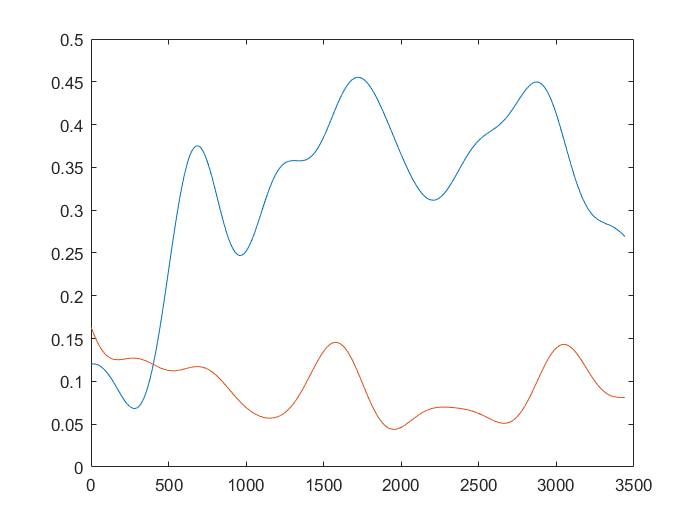

ans = 9

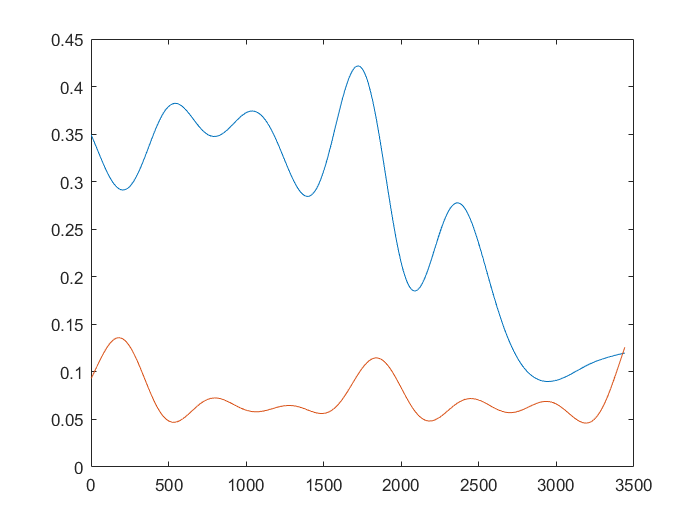

ans = 9

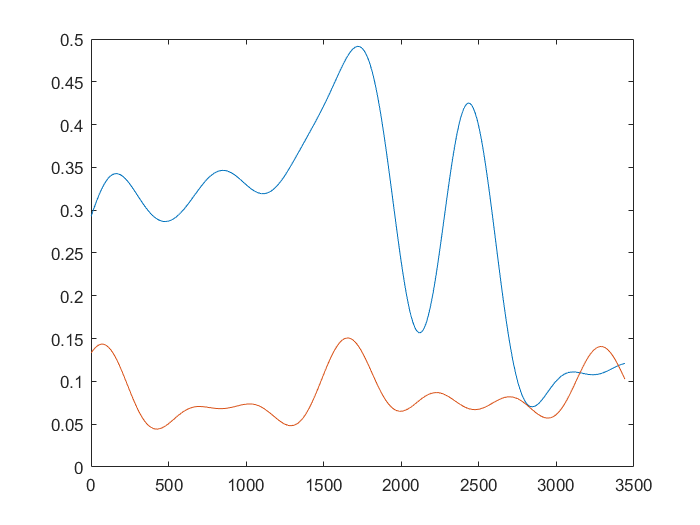

ans = 9

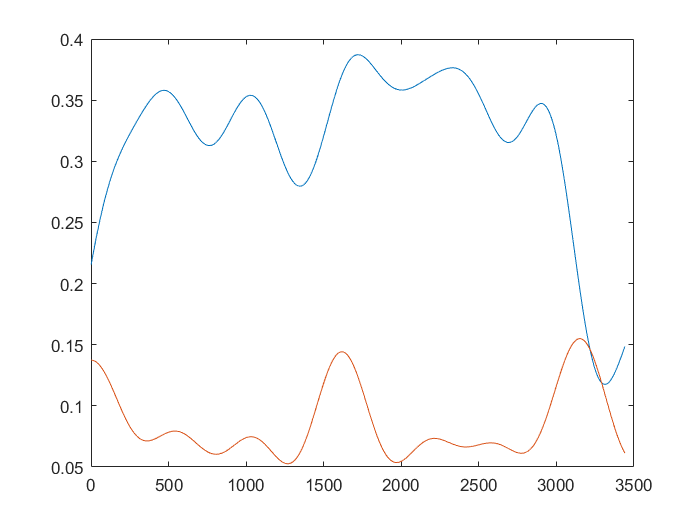

ans = 9

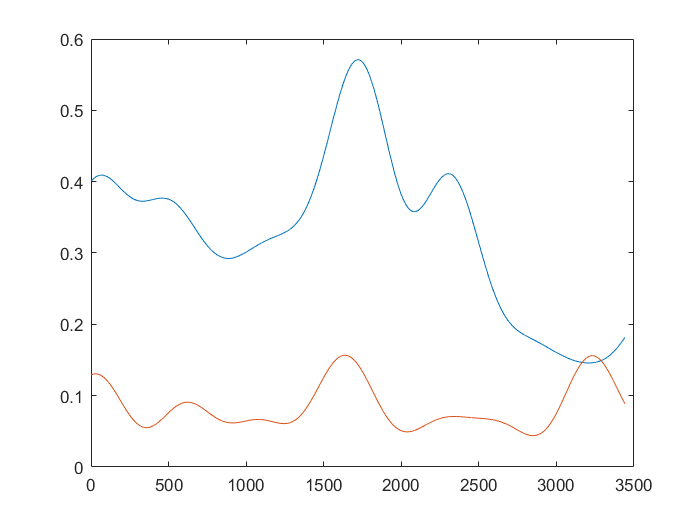

ans = 9

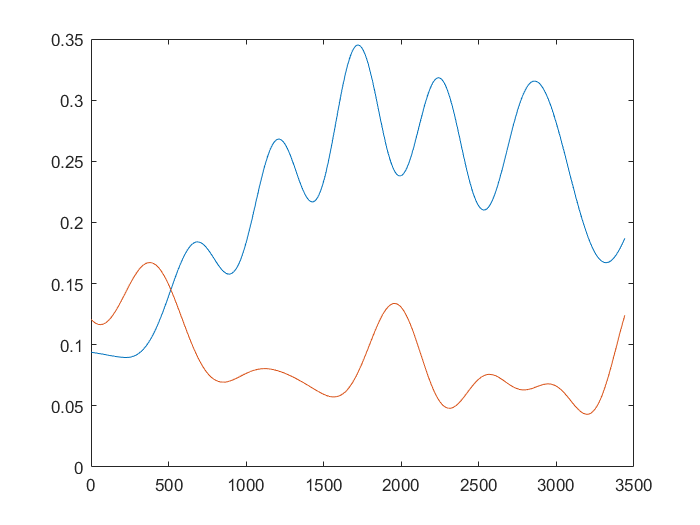

ans = 9

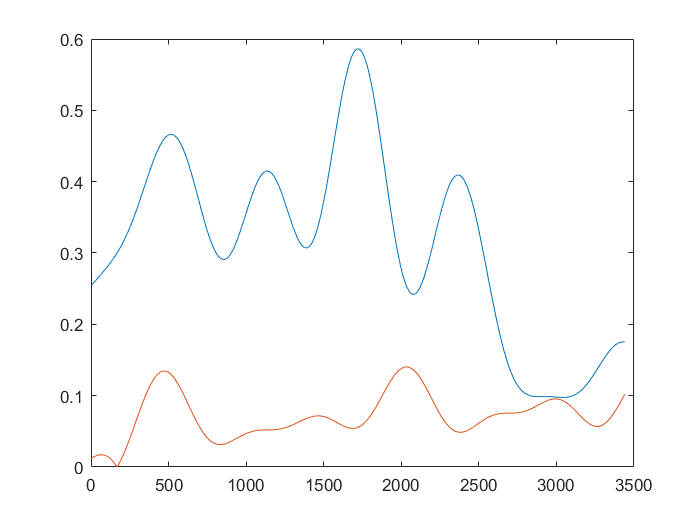

ans = 9

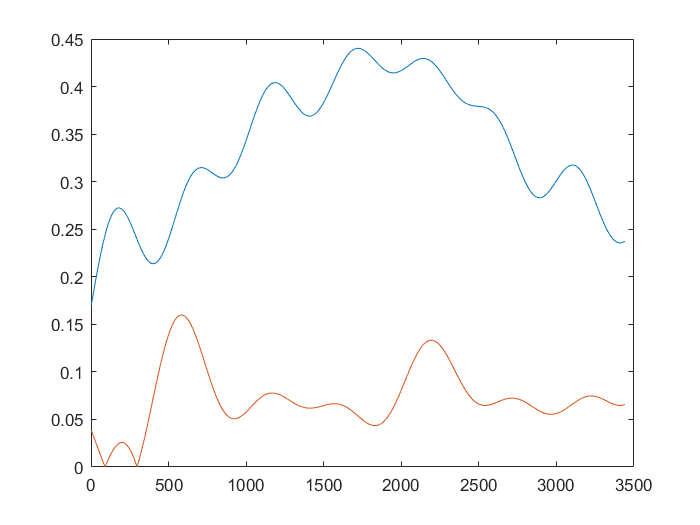

ans = 7

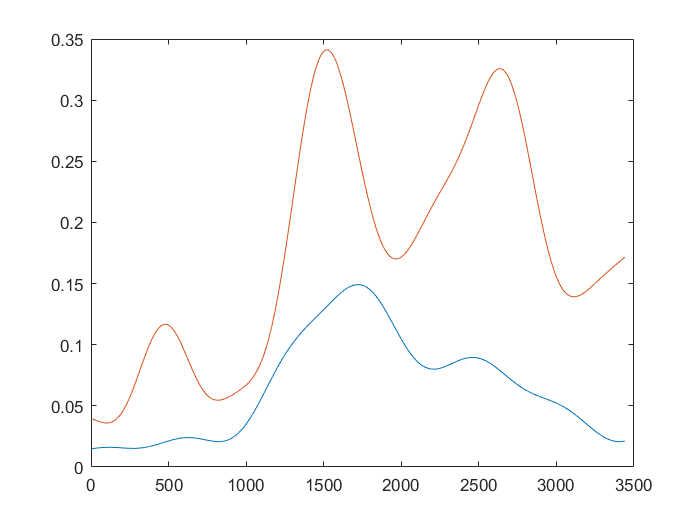

ans = 7

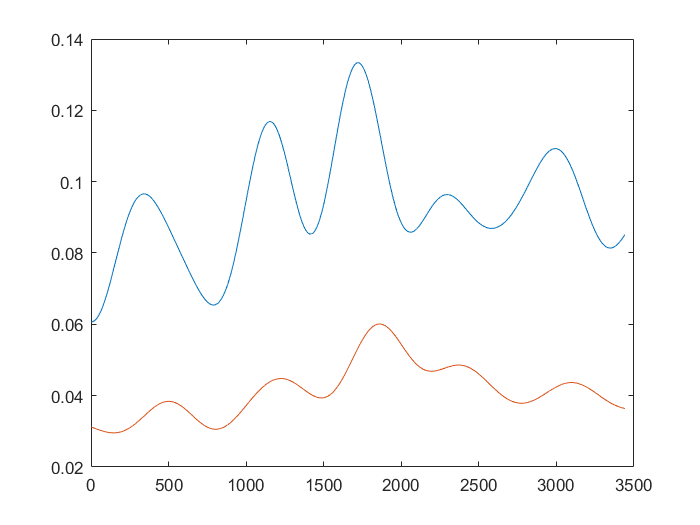

ans = 7

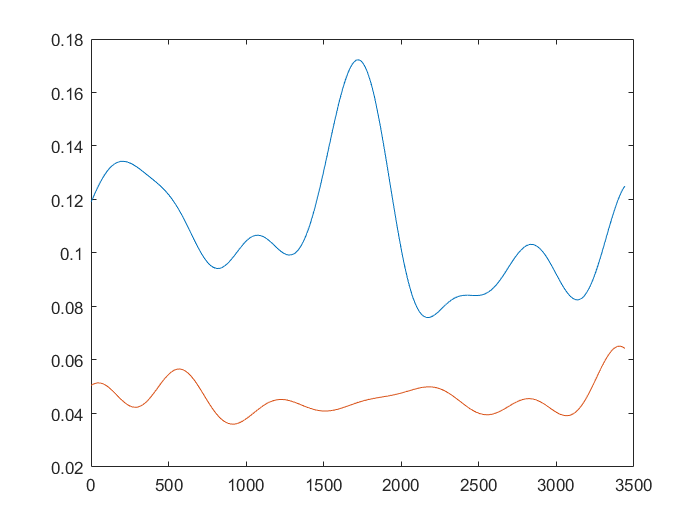

ans = 7

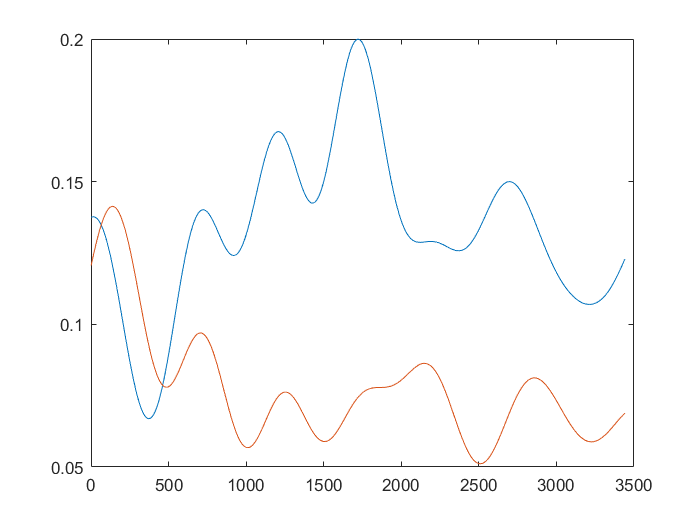

ans = 7

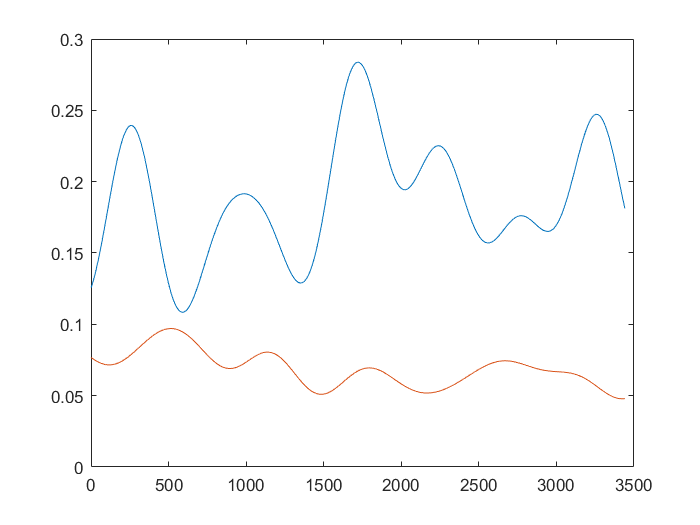

ans = 7

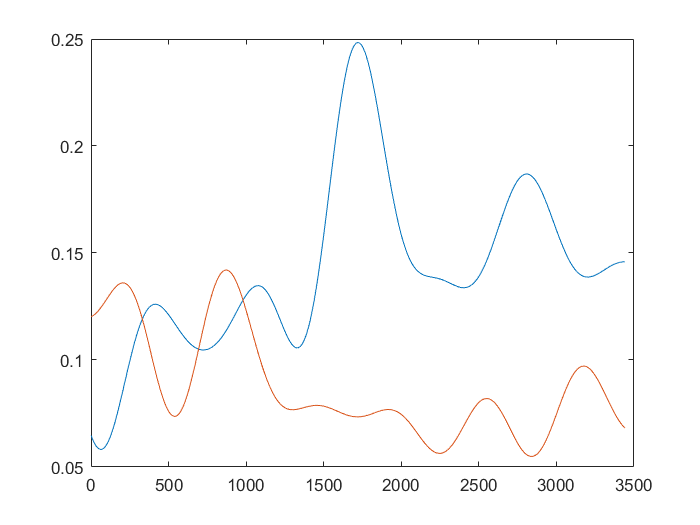

ans = 7

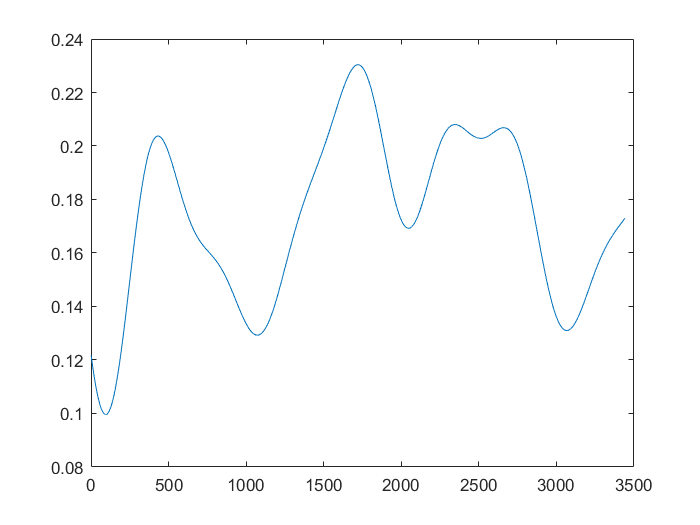

Index exceeds the number of array elements (6).


for index_sogg=1:num_soggetti
for index_casi=1:num_casi
    
for index_peak=1:N(index_casi, index_sogg)
    
    index_peak;
    N(index_casi, index_sogg)
    
    segnale=cell2mat(norm(index_casi, index_sogg));
    xpeak1=cell2mat(time_peaks(index_casi, index_sogg+index_sogg-1));
    xpeak2=cell2mat(time_peaks(index_casi, index_sogg+index_sogg));
    
    
    %subplot(num_soggetti, num_casi, index_sogg+(index_casi-1)*3)
    figure
    
    plot( segnale ( ( xpeak1(index_peak) -M/2) :  (xpeak1(index_peak) +M/2) , 1) )
    hold on
    plot( segnale ((xpeak2(index_peak) -M/2) : (xpeak2(index_peak) +M/2) , 2) )
  
end
end
end

*Obiettivo 6: calcolare e visualizzare la durata di attivazione media per ogni soggetto e per ogni prova.*

uso full_width at half maximum

...

*Obiettivo 7: Effettuare un permutation test sui dati tramite l'utilizzo di una funzione.*

%uso funzione my_permutation_test() 